Филимонов Степан РЛ6-31

Лабараторная номер 2

Задача:

Волновая функция, описывающая* состояние микрочастицы движущейся в сферически симметричном силовом поле* с расстоянием r до центра имеет вид: 

`Y(r, t) = A*exp(-r/a)*exp(-i*(E/h)*t)`

Здесь:

    r - расстояние силового центра;

    a - известная константа( a = 0.529177*10^(-10));

    E - полная энергия частицы независящая от времени.

**1) Определить** занечение постоянной А.

**2) Построить** графики (действительной, мнимой частей и модуля) **нормиравнной сферической гармоники** ВФ для*** s-*** и ***p- ***квантовых состояний.

Фото задания:

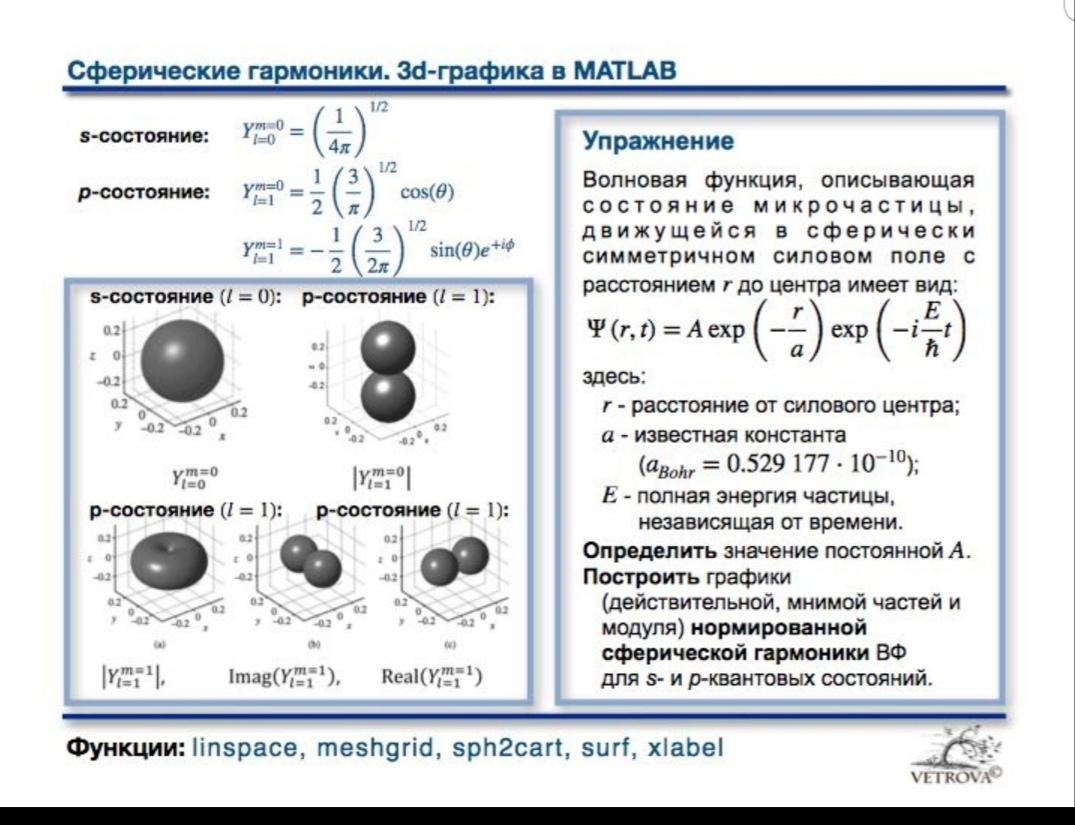

Теория:

**Сферические функции** — представляют собой угловую часть семейства ортогональных решений уравнения Лапласа, записанную в сферических координатах.

**Квантовое состояние** — любое возможное состояние, в котором может находиться квантовая система*. Чистое квантовое состояние может быть описано:

- *В волновой механике* — волновой функцией,

- *В матричной механике* — вектором состояния, или полным набором квантовых чисел для определённой системы.

Эти описания математически эквивалентны.

**Главное квантовое число** — целое число, для водорода и водородободобных атомов определяет возможные значения энергии.Главное квантовое число обозначается как n. Главное квантовое число связано с радиальным квантовым числом, nr, выражением: 

где *ℓ* — Оробитальное квантовое число и *nr* равно числу узлов радиальной части волновой функции.

**Оробитальное квантовое число **( *ℓ )* - число определяющие форму электронного облака.

**Магнитное квантовое число** (*m*) - характеризует ориентацию в пространстве орбитального момента импульса электрона или пространственное расположение атомной орбитали.

**квантовая система - Реальные или модельные системы, подчиняющиеся законам квантовой физики, называют квантовыми системами. Пример: электрон в атоме водорода.*

**1) Найдем коэфициент А:**


$$\int_V |\psi |^2 \textrm{dV}=1$$


Раскрываем в сферических кординатах:


$$\int_{r=0}^{\infty } \int_{\phi =0}^{2\pi } \int_0^{\pi } |\Psi |^2 {\;*r}^2 \;*a^3 *\sin \theta \;\mathrm{dr}\;d\phi \;d\theta =1$$


Сокращаем:


$$\int_{r=0}^{\infty } |\Psi |^2 *4*\;\pi \;\;*a^3 \mathrm{dr}=1$$


Подставим уравненние $\Psi \;=\;A*\exp \left(-\frac{r}{a}\right)*\exp \left(-i*\frac{E}{\hbar }*t\right)$:


$$\int_0^{\infty } |A*\exp \left(-\frac{r}{a}\right)*\exp \left(-i*\frac{E}{\hbar }*t\right)|^2 *4*\pi \;*a^3 \mathrm{dr}=1$$


Преобразуем и вынесем $4*\pi *|А|^2$, а так же подставим мнимую часть без минуса, чтобы сократить ее:


$$4\;*\pi \;*|A|^2 *\;a^3 \int_0^{\infty } \exp \left(-\frac{r}{a}\right)*\exp \left(-i*\frac{E}{\hbar }*t\right)*\exp \left(-\frac{r}{a}\right)*\exp \left(i*\frac{E}{\hbar }*t\right)\mathrm{dr}=1$$


, тогда:


$$4\;*\pi \;*|A|^2 \;*a^3 \int_0^{\infty } \frac{a^2 }{2}*\exp \left(-\frac{2*r}{a}\right)\mathrm{dr}=1$$


это


$$4\pi |A|^2 \frac{a^3 }{-4}e^{\frac{-2r}{a}} |_0^{\infty } =1$$
 

Преобразуем:


$$A=\sqrt{\frac{1}{4{\pi a}^3 }}$$


Так как a = 0.529177*10^(-10) , то А равно $\approx$ $1,465\;{\cdot 10}^{15}$

Проведем проверку, решим интеграл в MATLAB, используем библиотеку Math Toolbox

Код Matlab:

syms x;
a = 0.529177*1e-10;
A = sqrt(1 /( 4*pi*int(exp(-2*x/a)*x.^2,0, inf)));
A = double(A)

A = 1.4656e+15

**2) Построим графики:**

Код Matlab:

Постоянные значения:

 cla reset;
 i = sqrt(-1);
 phi = linspace(0, 2*pi); 
 theta = linspace(0, pi);
 [Phi, Theta] = meshgrid(phi, theta);
 Azimuth = Phi;
 Elevation = (pi/2) - Theta;
 rSstatus = sqrt(1/(4*pi));
 rPm0status = (1/2)*sqrt(3/pi)*cos(Theta);
 rPm1status = (-1/2)*sqrt(3/(2*pi)).*sin(Theta).*exp(i.*Phi);

График для ***s-состояния ***$Y_{l=0}^{m=0}$:

plot(Azimuth, Elevation, rSstatus, 1); %*(см. ниже)
title('Y_{l=0}^{m=0}');
xlabel('x',"Position",[-0.3, -0.76]);
ylabel('y',"Position",[-0.66, -0.4]);
zlabel('z','Rotation',0);

Графики для ***p-состояния ***${|Y}_{l=1}^{m=0} |$:

plot(Azimuth, Elevation, abs(rPm0status), 2);
title('|Y_{l=1}^{m=0}|')
xlabel('x',"Position",[-0.5, -1.05]);
ylabel('y',"Position",[-0.9, -0.7]);
zlabel('z','Rotation',0);

Графики для ***p-состояния ***${|Y}_{l=1}^{m=1} |$:

plot(Azimuth, Elevation, abs(rPm1status), 4); 
title('|Y_{l=1}^{m=1}|');
xlabel('x',"Position",[-0.2, -0.75]);
ylabel('y',"Position",[-0.7, -0.3]);
zlabel('z','Rotation',0);

Графики для ***p-состояния ***$|\textrm{imag}\left(Y_{l=1}^{m=1} \right)|$:

plot(Azimuth, Elevation, abs(imag(rPm1status)), 5);
title('|Imag(Y_{l=1}^{m=1})|');
xlabel('x',"Position",[-0.17, -0.7]);
ylabel('y',"Position",[-0.47, -0.25]);
zlabel('z','Rotation',0);

Графики для ***p-состояния ***$|\textrm{real}\left(Y_{l=1}^{m=1} \right)|$:

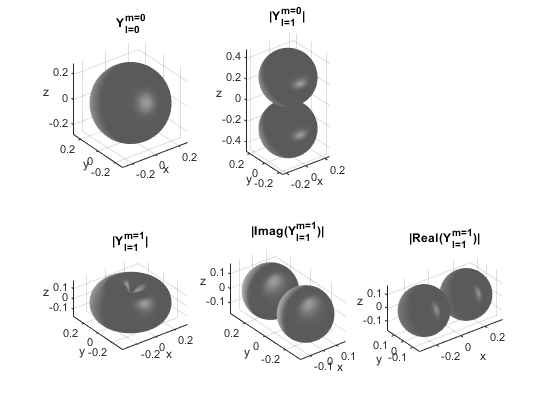

plot(Azimuth, Elevation, abs(real(rPm1status)), 6);
title('|Real(Y_{l=1}^{m=1})|');
xlabel('x',"Position",[-0.17, -0.6]);
ylabel('y',"Position",[-0.7, -0.25]);
zlabel('z','Rotation',0);

Время: 

 datetime('now')

ans = datetime
   11-Nov-2021 10:13:46


*Функция создания графика:

 function plot(Azimuth, Elevation, r, num)
   subplot(2, 3, num)
   [X,Y,Z] = sph2cart(Azimuth,Elevation,r);
   surfl(X,Y,Z);  
   axis('equal');
   colormap("gray");
   shading interp;
 end